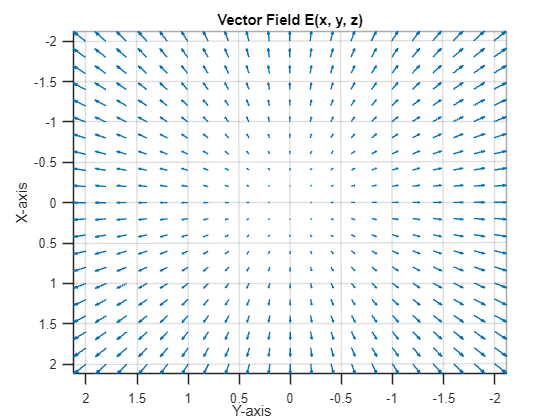

% 🌟✨🖥️ MATLAB Code by Seyed Mohammad Sajadi 🖥️✨🌟
% Student Number: 402448040

% Define the vector field function
E_x = @(x, y, z) x;
E_y = @(x, y, z) y;
E_z = @(x, y, z) 0 * z;

% Define the grid
[x, y, z] = meshgrid(-2:0.2:2, -2:0.2:2, -2:0.2:2);

% Calculate the vector field values
U = E_x(x, y, z);
V = E_y(x, y, z);
W = E_z(x, y, z);

% Plot the vector field using quiver3
figure;
quiver3(x, y, z, U, V, W);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Vector Field E(x, y, z)');
axis tight;
grid on;

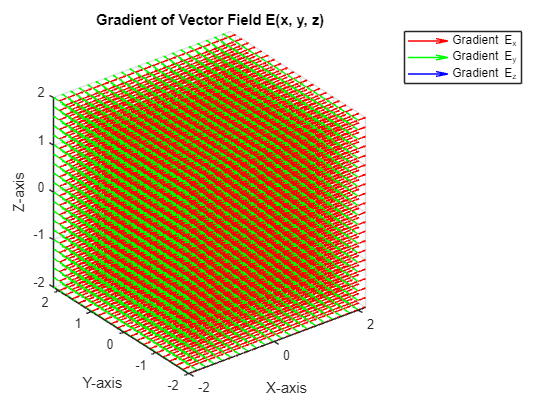

% Define the vector field function
E_x = @(x, y, z) x;
E_y = @(x, y, z) y;
E_z = @(x, y, z) 0 * z;

% Define the grid
[x, y, z] = meshgrid(-2:0.2:2, -2:0.2:2, -2:0.2:2);

% Calculate the gradient of each component
[Ex_dx, Ex_dy, Ex_dz] = gradient(E_x(x, y, z), 0.2, 0.2, 0.2);
[Ey_dx, Ey_dy, Ey_dz] = gradient(E_y(x, y, z), 0.2, 0.2, 0.2);
[Ez_dx, Ez_dy, Ez_dz] = gradient(E_z(x, y, z), 0.2, 0.2, 0.2);

% Plot the gradient vectors using quiver3
figure;
quiver3(x, y, z, Ex_dx, Ex_dy, Ex_dz, 'r');
hold on;
quiver3(x, y, z, Ey_dx, Ey_dy, Ey_dz, 'g');
quiver3(x, y, z, Ez_dx, Ez_dy, Ez_dz, 'b');
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Gradient of Vector Field E(x, y, z)');
axis tight;
grid on;
legend('Gradient E_x', 'Gradient E_y', 'Gradient E_z');
hold off;